## Creating Surrogates

This script steps through the process of creating a surrogate performance space in MATLAB. This is equivalent to the R Markdown file "Five-creating_surrogates.Rmd". 

First we define the ranges of parameters for the performance spaces. 

- Reynolds number (`Re`) in the range of 10,000 to 10,000,000

- Angle of Attack (`aoa`) in the range of 0 to 15 degrees

- Camber (`camber`) in the range of 0.005 to 0.20

Re_low = 1e6;
Re_high = 1e9;
aoa_low = 0;
aoa_high = 15;
camber_low = 0.005;
camber_high = 0.20;

Run each section of the code to generate necessary items to produce a surrogate performance space for each method. 

### Grid Sampling 

Actual results of the grid sampling across the three parameters can be plotted in a grid map to create a performance space. First, we load, sort, and join the parameter set and the results. 

grid_params = readtable("../data/parameters/grid_Params_noLogRe.csv");
grid_params.Properties.VariableNames = {'Re', 'aoa', 'camber'};
grid_results = readtable("../results/grid_noLogRe_results.csv");
grid_results = sortrows(grid_results, "sim");
grid_data = [grid_params,grid_results];

Next, we subset the data to only include the Re = 50050000, which is the midpoint of Re range.

grid_midRe_data = table2array(grid_data(grid_data.Re == 500500000,5));

Set up a grid for plotting: 

aoa_values = linspace(0, 15, 7);
camber_values = linspace(0.005,0.2,7);
[aoa_grid,camber_grid] = meshgrid(aoa_values, camber_values);
output_grid = reshape(grid_midRe_data, [7,7]);

Then, we can plot the performance space: 

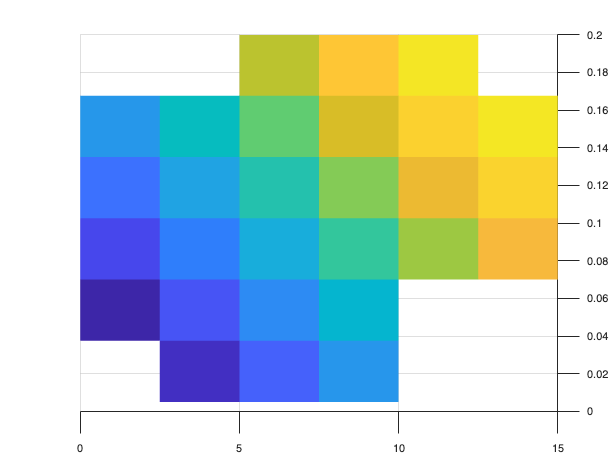

figure1 = figure('Name','Figure');
axes1 = axes('Parent',figure1);
surf(aoa_values, camber_values, output_grid),shading flat
hold(axes1,'on');
view(axes1,[0.9 90]);
hold(axes1,'off');

### Generalized Polynomial Chaos (gPC)

Here, we use generalized polynomial chaos (gPC) to generate parameter sampling set for running full simulations. 

Add the proper folder to the MATLAB environment before getting started: 

addpath('../src/matlab/gpc')

Run the following function to generate the proper gPC space: 


Loading gPC Data Structures...
   --> Done!

gPC Surrogate Info: 
    --> # of parameters: 3
    --> Highest polynomial degree: 6
    --> # of terms in expansion: 84

Loading Output Metrics...
    --> Done!

Simulations fully finished/converged: 263
# OF UNKNOWN SPECTRAL COEFFS: 84
RANK OF PSI^T*PSI 84

Computing gPC Coefficients...
    --> calculated gPC coeffs!

------------------------------------------

    --> Recover the training dataset


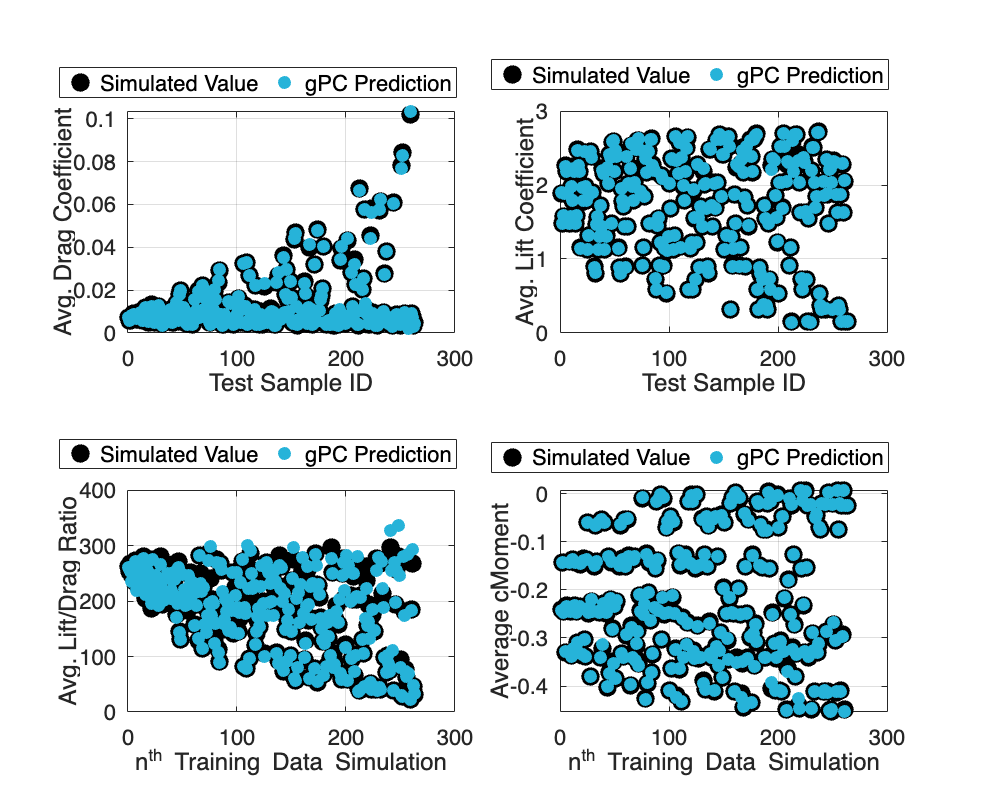


      STATS (Percent Differences):
Data | avg  | med  | min  |  max  | stdev
 CD  | 4.37 | 2.34 | 0.01 | 50.37 | 5.71
 CL  | 0.45 | 0.29 | 0.00 |  6.90 | 0.65
 L/D | 4.59 | 2.44 | 0.02 | 52.80 | 6.03
 CM  | 1.84 | 0.71 | 0.01 | 54.88 | 5.00



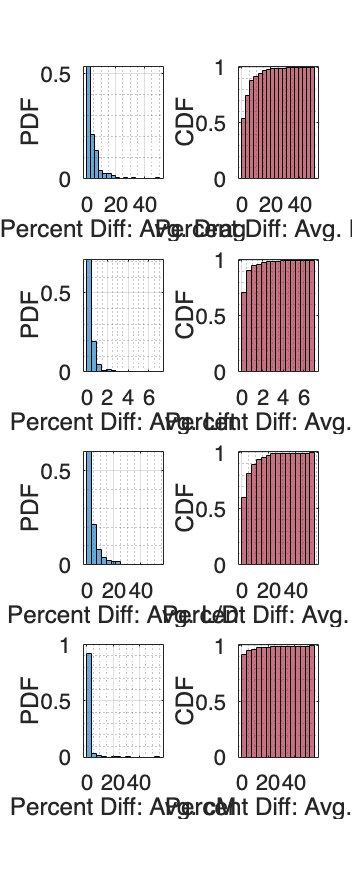

    --> Finished recovering the training dataset

    --> Hit any [KEY] to continue...

------------------------------------------

    --> Validate against the TEST dataset


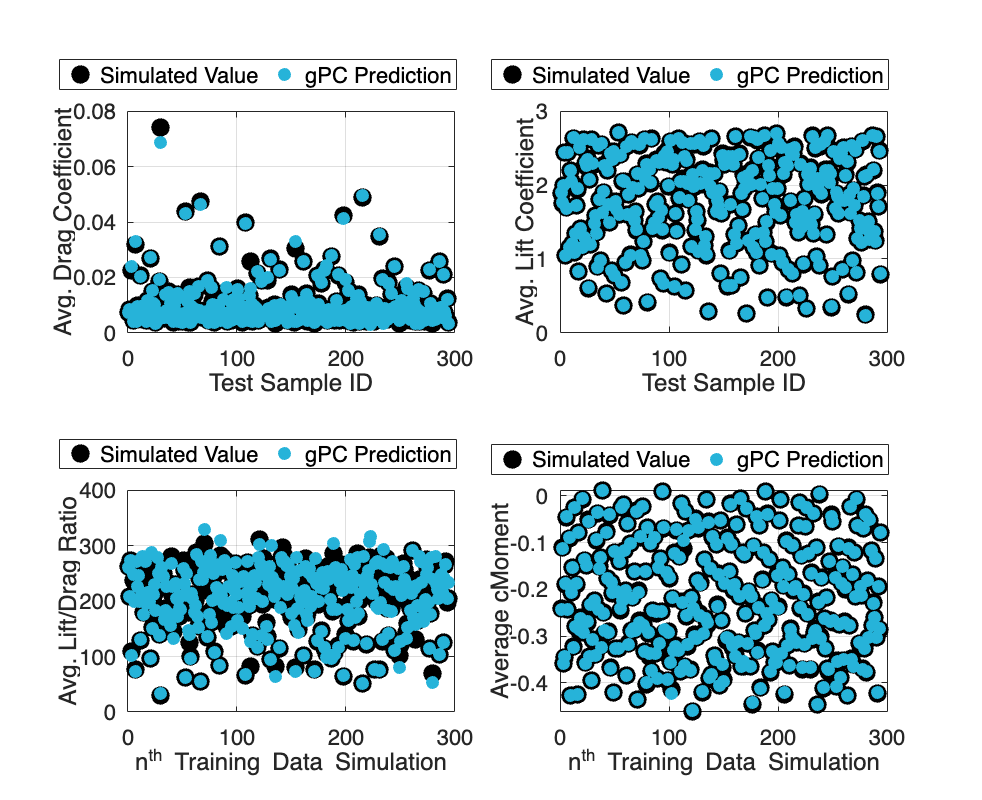


      STATS (Percent Differences):
Data | avg  | med  | min  |  max  | stdev
 CD  | 4.91 | 3.21 | 0.00 | 37.60 | 5.39
 CL  | 0.40 | 0.30 | 0.00 |  2.49 | 0.40
 L/D | 5.10 | 3.14 | 0.01 | 57.42 | 6.22
 CM  | 1.19 | 0.60 | 0.01 | 28.98 | 2.50



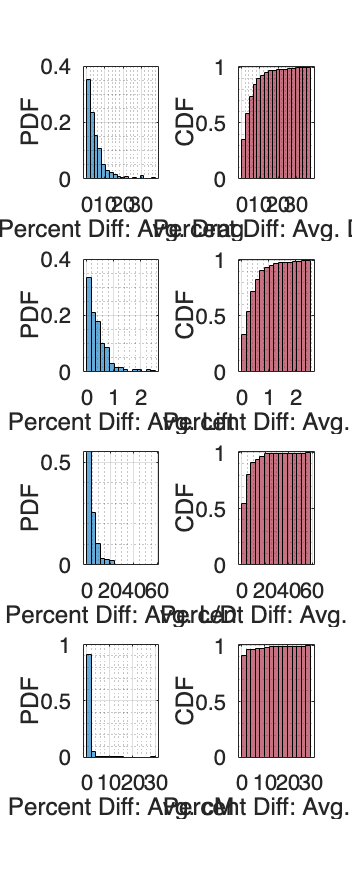

[scoeff, alphaMAT] = perform_gPC_Validation();

We now have the gPC coefficients `scoeff` for lift returned by the model training and the `alphaMAT` required to generate the surrogate. 

[aoa_grid, camber_grid] = meshgrid(linspace(aoa_low, aoa_high, 100), ...
    linspace(camber_low, camber_high, 100));
aoa_list = reshape(aoa_grid,[1, 100*100]);
camber_list = reshape(camber_grid, [1, 100*100]);
Re_list = 500500000.*ones(1, 100*100);

gPC_lift = zeros(1,100*100);

for j=1:length(aoa_list )
   
    %-----------------------------------
    % Get Parameter Combination
    %-----------------------------------
    ReTest = Re_list(1,j);
    AoATest = aoa_list(1,j);
    CamberTest = camber_list(1,j);
    
    %-----------------------------------------------------
    % Re: Get Transformed FIRST Evaluation Point
    %-----------------------------------------------------
    ReVal = transform_Values_To_Minus1_Plus1(ReTest,Re_low,Re_high);

    %-----------------------------------------------------
    % AoA: Get Transformed SECOND Evaluation Point
    %-----------------------------------------------------
    AoAVal = transform_Values_To_Minus1_Plus1(AoATest,aoa_low,aoa_high);
    
    %-----------------------------------------------------
    % Camber: Get Transformed Third Evaluation Point
    %-----------------------------------------------------
    CamberVal = transform_Values_To_Minus1_Plus1(CamberTest,camber_low,camber_high);

    %-----------------------------------------------------
    % SPECIFIC PARAMETER COMBINATION
    %-----------------------------------------------------
    VEC = [ReVal AoAVal CamberVal];

    %----------------------------------------------------------------
    %       Evaluate Multidim. Legendre Polys for Metric
    %----------------------------------------------------------------
    % Coefficiet of Lift
    gPC_CL(1,j) = evaluate_MultiDim_Legendre_Poly(scoeff,alphaMAT,VEC); 
        
end

gPC_CL_grid = reshape(gPC_CL, [100, 100]);

Now we can plot the surrogate: 

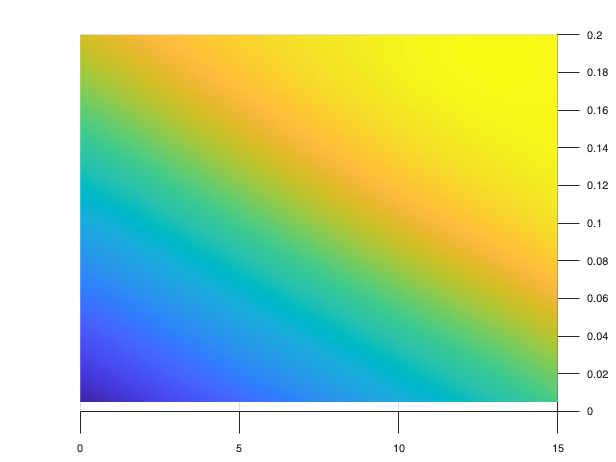

figure2 = figure('Name','Figure');
axes2 = axes('Parent',figure2);
surf(aoa_grid, camber_grid, gPC_CL_grid),shading flat
hold(axes2,'on');
view(axes2,[0.9 90]);
hold(axes2,'off');

### Trained Neural Network

Coming soon!